## **Task 1**

fprintf("----------------------Task1---------------------")

----------------------Task1---------------------

%1.1a probality to select right answer
p = 0.6;
n = 4;
prob_ra =  (1*p + 1/n*(1-p)) * 100;
fprintf("The prob to select right answer is: %d%%", prob_ra)

The prob to select right answer is: 70%

%1.1b probability of the student to known the answer 
%when he selects the right answer
p = 0.7;
n = 5;
prob_sra = (1*p/(1*p + 1/n*(1-p)))*100;
fprintf("The prob to know the answer when sra is : %1.3g%%\n", prob_sra)

The prob to know the answer when sra is : 92.1%


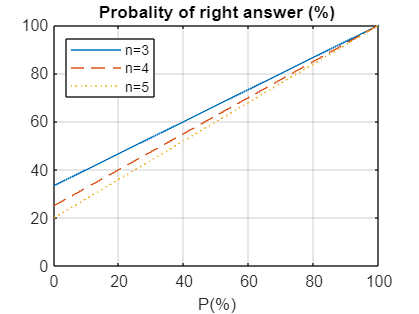

%1.1c Draw a plot with the probability of the student to 
%select the right answer as a function of the probability 
n1 = 3;
n2 = 4;
n3 = 5;
p = [0, 100];
proba1 = (1*(p./100) + 1/n1*(1-(p./100))) * 100;
proba2 = (1*(p./100) + 1/n2*(1-(p./100))) * 100;
proba3 = (1*(p./100) + 1/n3*(1-(p./100))) * 100;

figure(1)
plot(p,proba1,  p,proba2,'--',  p,proba3,':')
xlabel('P(%)')
title('Probality of right answer (%)')
legend('n=3', 'n=4', 'n=5','Location', 'northwest')
axis([0 100 0 100])
grid on

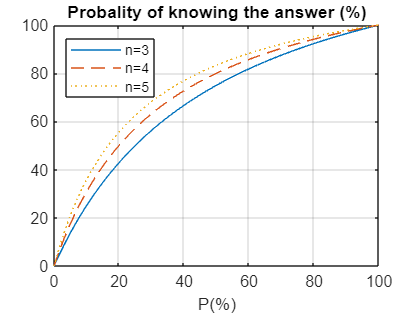

%1.1d Draw a plot with the probability of the student to 
%select the right answer when he selects the right answer 
% as a function of the probability 𝑝
n1 = 3;
n2 = 4;
n3 = 5;
p = linspace(0, 100, 100);
proba1_sra = (1* (p./100)./ (1*(p./100) + 1/n1*(1-(p./100))))*100;
proba2_sra = (1* (p./100)./ (1*(p./100) + 1/n2*(1-(p./100))))*100;
proba3_sra = (1* (p./100)./ (1*(p./100) + 1/n3*(1-(p./100))))*100;

figure(2)
plot(p,proba1_sra,  p,proba2_sra,'--',  p,proba3_sra,':')
xlabel('P(%)')
title('Probality of knowing the answer (%)')
legend('n=3', 'n=4', 'n=5','Location', 'northwest')
axis([0 100 0 100])
grid on

%%%%%conclusion: the more student studies and answer the right answer, the
%%%%%more the graph rise up.

## **Task 2**

fprintf("----------------------Task2---------------------")

----------------------Task2---------------------

%2.a
p = 10^-2; % BER
n = 100*8; % Bits of package
proba_no_error = (nchoosek(n,0) * p^0 * (1 - p)^(n - 0))*100;
fprintf("The probabality to receive no error is: %1.3g%%\n", proba_no_error);

The probabality to receive error is: 0.0322%


%2.b
p = 10^-3; %BER
n = 1000*8; % Bits of package
proba_one_error = (1 - nchoosek(n,1) * p^1 * (1 - p)^(n - 1))*100;
fprintf("The probabality to receive exactly \n one error is: %1.4g%%\n", proba_one_error);

The probabality to receive exactly 
 one error is: 99.73%


%2.c
p = 10^-4; %BER
n = 200*8; % Bits of package
proba_one_or_more_error = (1 - nchoosek(n,0) * p^0 * (1 - p)^(n - 0))*100;
fprintf("The probabality to receive exactly \n one or more errors is: %1.6g%%\n", proba_one_or_more_error);

The probabality to receive exactly 
 one or more errors is: 14.7863%


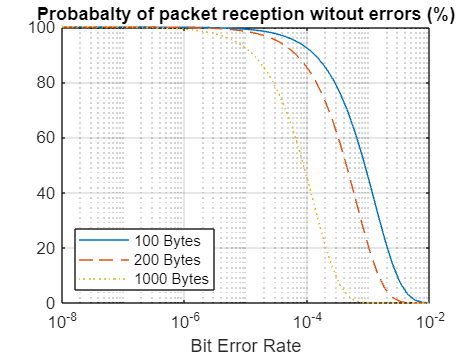

%2.d Draw a plot using a logarithmic scale for the X-axis - 
% proba without error
p = logspace(-8, -2); % BER: 10^-8 to 10^-2
n1 = 100*8; % data frame
n2 = 200*8; % data frame
n3 = 1000*8; % data frame
proba1_no_error_x = (nchoosek(n1, 0) * 1 * (1-p).^(n1-0))*100;
proba2_no_error_x = (nchoosek(n2, 0) * 1 * (1-p).^(n2-0))*100;
proba3_no_error_x = (nchoosek(n3, 0) * 1 * (1-p).^(n3-0))*100;
figure(3)
semilogx(p, proba1_no_error_x, p, proba2_no_error_x, '--', p, proba3_no_error_x, ':');
xlabel("Bit Error Rate");
title("Probabalty of packet reception witout errors (%)");
legend('100 Bytes', '200 Bytes', '1000 Bytes','Location', 'southwest');
grid on

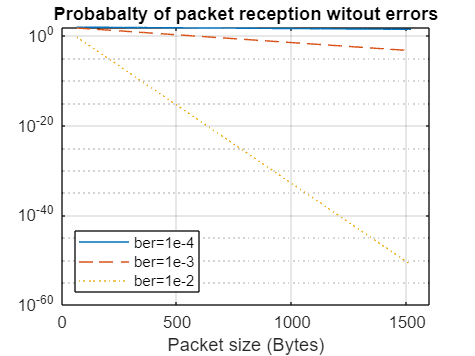

%2.e Draw a plot using a logarithmic scale for the y-axis - 
% proba without error
dataFrameSize = 64:1518; % data frame size
p1 = 10^-4; % BER
p2 = 10^-3; % BER
p3 = 10^-2; % BER
proba1_no_error_y = zeros(1, length(dataFrameSize));
proba2_no_error_y = zeros(1, length(dataFrameSize));
proba3_no_error_y = zeros(1, length(dataFrameSize));
for i = 1:length(dataFrameSize)
    proba1_no_error_y(i) = ( nchoosek(dataFrameSize(i)*8, 0) * 1 * (1-p1)^(dataFrameSize(i)*8-0) )*100;
    proba2_no_error_y(i) = ( nchoosek(dataFrameSize(i)*8, 0) * 1 * (1-p2)^(dataFrameSize(i)*8-0) )*100;
    proba3_no_error_y(i) = ( nchoosek(dataFrameSize(i)*8, 0) * 1 * (1-p3)^(dataFrameSize(i)*8-0) )*100;
end
figure(4)
semilogy(dataFrameSize , proba1_no_error_y, dataFrameSize , proba2_no_error_y, '--', dataFrameSize , proba3_no_error_y, ':');
axis([0 1601 10^-60 100]);
xlabel("Packet size (Bytes)");
title("Probabalty of packet reception witout errors");
legend('ber=1e-4', 'ber=1e-3', 'ber=1e-2','Location', 'southwest');
grid on